Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
fft_size = 2^(nextpow2(L));
t = (0:L-1)*T;        % Time vector

S = cos(2*pi*500*t) + 1i * sin(2*pi*500*t);

Y = fft(S,fft_size);
Y_shift = fftshift(Y);

Y_shift = 	1.0e+03 *

   1.5000 - 0.0000i  -0.3234 - 0.3624i   0.0367 - 0.3219i   0.1031 - 0.0728i  -0.0348 - 0.0080i  -0.0547 - 0.0998i   0.0343 - 0.0968i   0.0335 - 0.0137i  -0.0313 - 0.0153i  -0.0188 - 0.0668i   0.0298 - 0.0468i   0.0104 - 0.0017i  -0.0260 - 0.0210i  -0.0024 - 0.0500i   0.0238 - 0.0233i  -0.0019 - 0.0001i  -0.0194 - 0.0248i   0.0068 - 0.0373i   0.0168 - 0.0103i  -0.0086 - 0.0026i  -0.0123 - 0.0264i   0.0114 - 0.0265i   0.0098 - 0.0033i  -0.0115 - 0.0066i  -0.0055 - 0.0258i   0.0128 - 0.0174i   0.0034 - 0.0003i  -0.0115 - 0.0106i   0.0004 - 0.0233i   0.0117 - 0.0100i  -0.0018 - 0.0002i  -0.0095 - 0.0139i   0.0049 - 0.0194i   0.0089 - 0.0047i  -0.0054 - 0.0020i  -0.0061 - 0.0158i   0.0075 - 0.0147i   0.0052 - 0.0014i  -0.0072 - 0.0048i  -0.0023 - 0.0162i   0.0084 - 0.0100i   0.0015 - 0.0000i  -0.0073 - 0.0077i   0.0013 - 0.0151i   0.0077 - 0.0058i  -0.0018 - 0.0004i  -0.0059 - 0.0101i   0.0041 - 0.0128i   0.0059 - 0.0026i  -0.0042 - 0.0019i


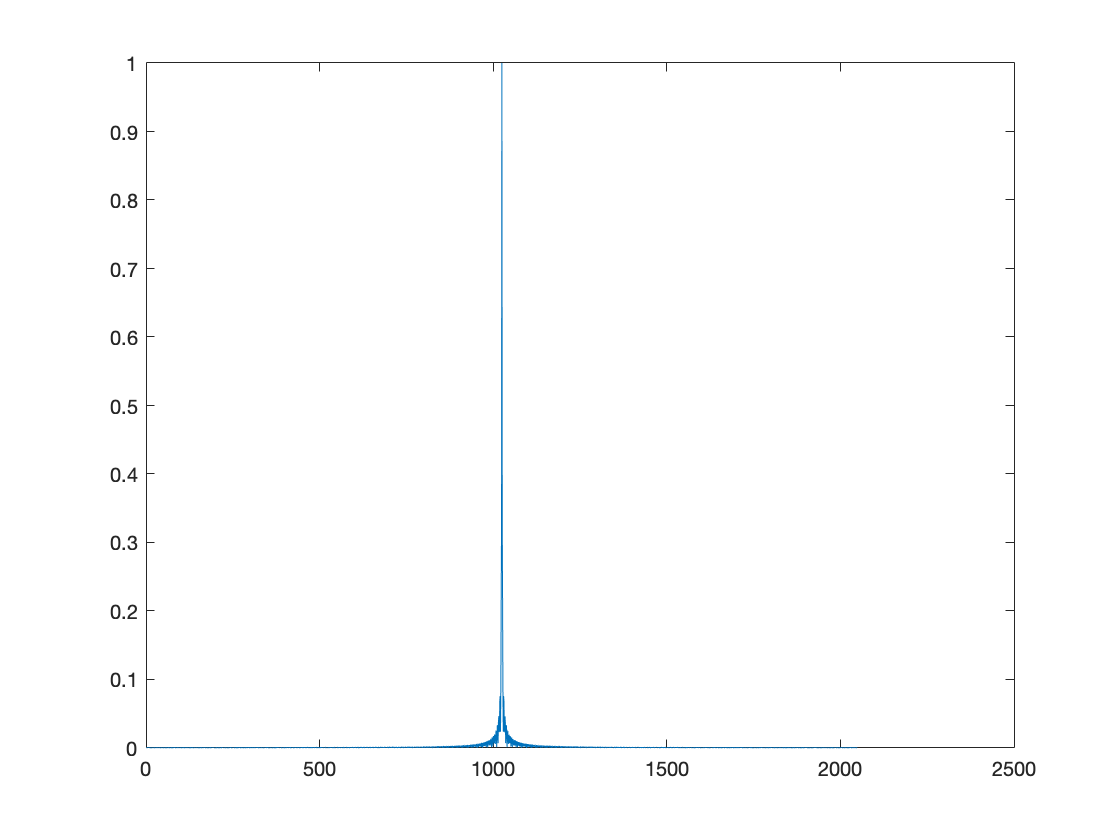

f = Fs * (0:fft_size - 1)/L
plot(abs(Y/L));

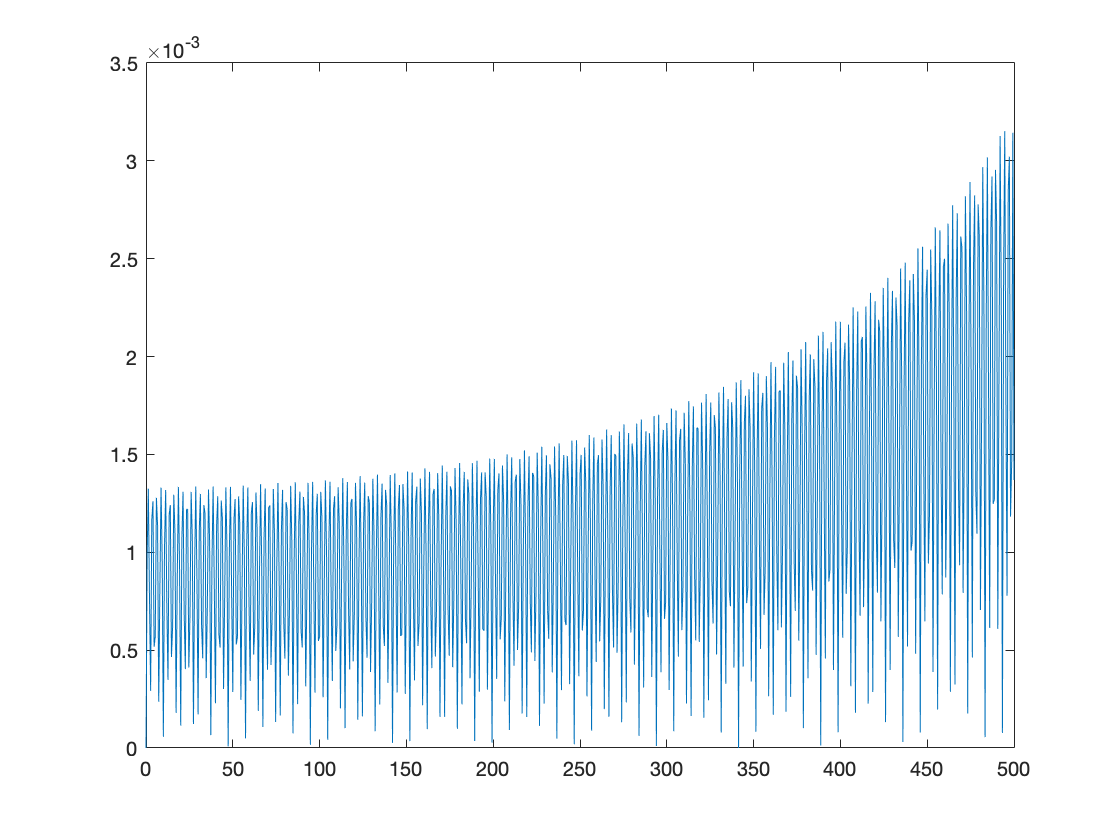

f = Fs*(0:(L/2))/L;
plot(f,P1) 

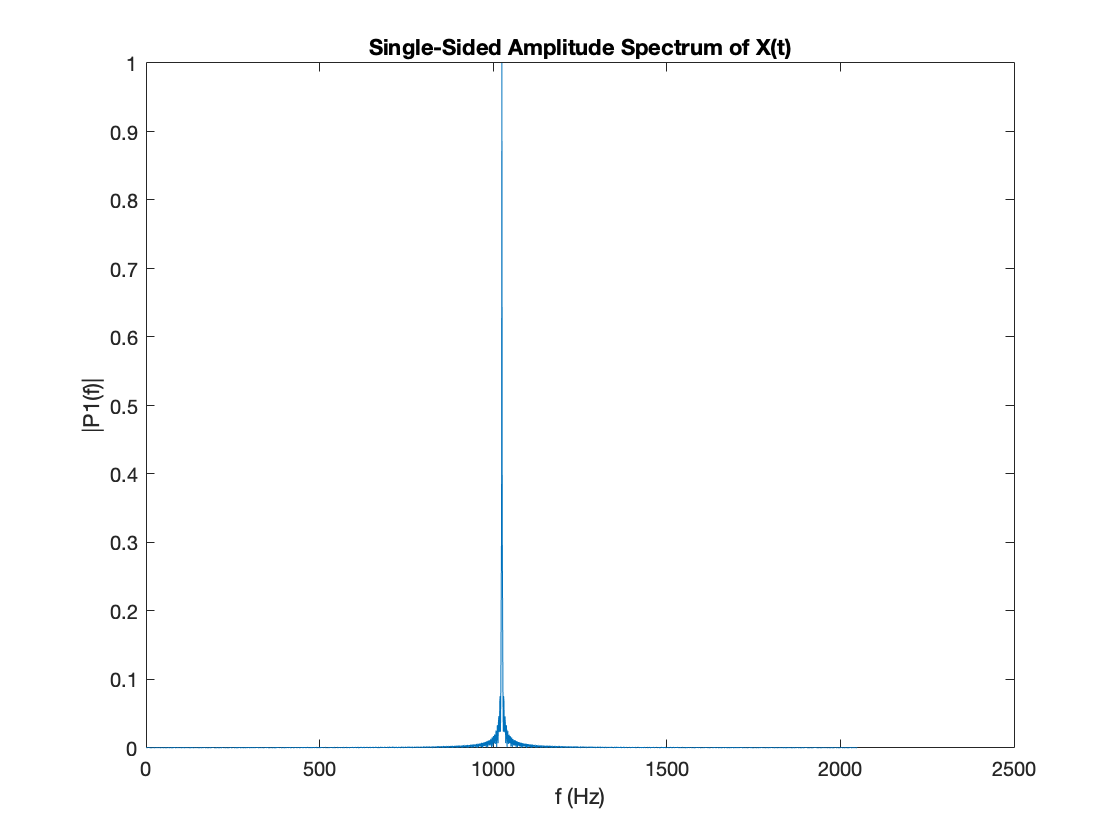

plot(P2)
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

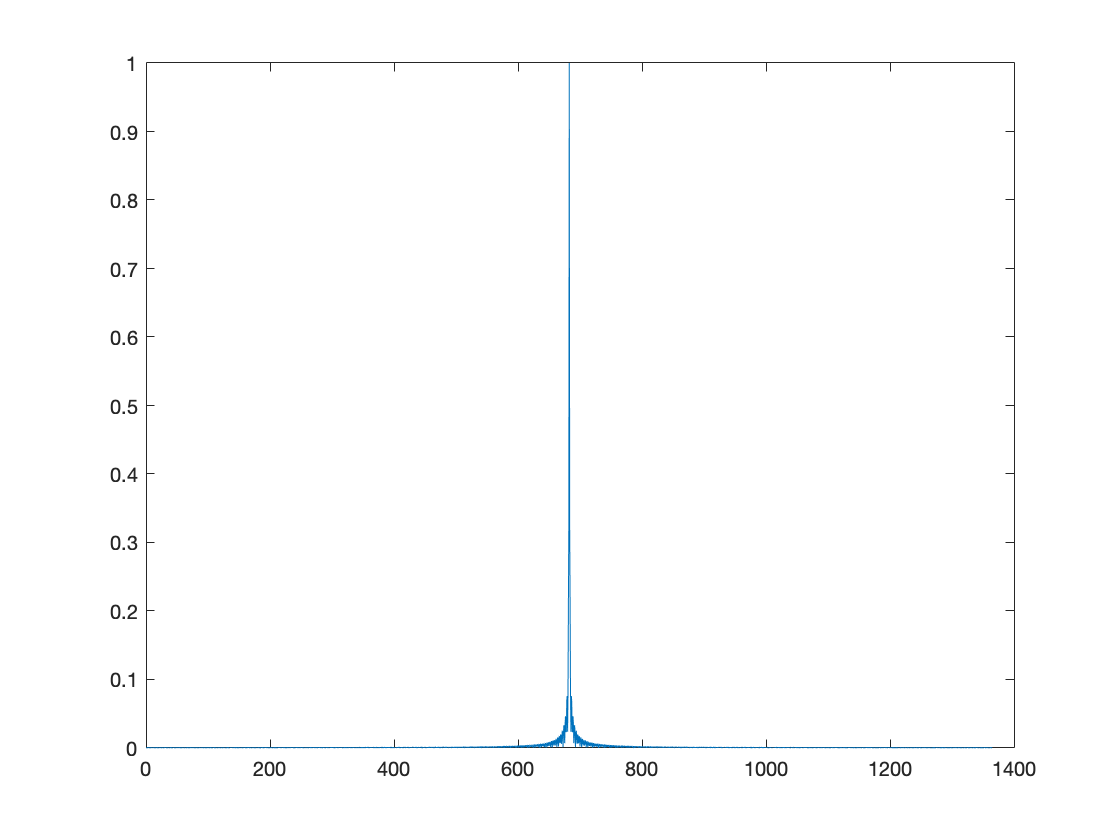

f = Fs *(0:fft_size - 1)/L;
plot(f,P2)